# Module 3: Operations, Functions and Plotting of Numeric Arrays

## 1. Operations of Arrays

### 1.1 Scalar and Array

v = 1:3; % generate vector v
A = [v;v;v] % generate matrix A

A =      1     2     3
     1     2     3
     1     2     3



v+1 % "element+1"

ans =      2     3     4


A-1 % "element-1"

ans =      0     1     2
     0     1     2
     0     1     2


v*4 % "element*4"

ans =      4     8    12


2*A % scalar multiplication, "element*2"

ans =      2     4     6
     2     4     6
     2     4     6


A/2 % division, "element/2"

ans =     0.5000    1.0000    1.5000
    0.5000    1.0000    1.5000
    0.5000    1.0000    1.5000


2./v % element-wise division, note the . here!

ans =     2.0000    1.0000    0.6667


3./A % element-wise division, note the . here!

ans =     3.0000    1.5000    1.0000
    3.0000    1.5000    1.0000
    3.0000    1.5000    1.0000


v.^2 % element-wise power, note the . here!

ans =      1     4     9


2.^v

ans =      2     4     8


(-1).^v % caution: the parenthesis here is important! try -1.^v by yourself and explain why (hint:order of operation)

ans =     -1     1    -1


A.^2 % also element-wise power

ans =      1     4     9
     1     4     9
     1     4     9


A^2 % NOTE THE DIFFERENCE! THIS IS MATRIX POWER (we won't cover it now --just know the difference!!!)

ans =      6    12    18
     6    12    18
     6    12    18


**Hint: **check out this [page](https://www.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html#bvg3oy_-2?s_tid=doc_ta) if you want to learn more about arithmetic operators in MATLAB!

***Example 1:  Create row vector ***$\left\lbrack \begin{array}{ccccc}
1 & -2 & 3 & -4 & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$***, total of 20 terms.***

x = 1:20;
x

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x(2:2:end) % this is the part that need to be changed

ans =      2     4     6     8    10    12    14    16    18    20


y = -x(2:2:end);
y % this is what we need!

y =     -2    -4    -6    -8   -10   -12   -14   -16   -18   -20


x(2:2:end) = y;
x

x =      1    -2     3    -4     5    -6     7    -8     9   -10    11   -12    13   -14    15   -16    17   -18    19   -20


***Example 2:  Create row vector ***$\left\lbrack \begin{array}{ccccc}
1 & \frac{1}{2} & \frac{1}{3} & \ldotp \ldotp \ldotp  & \frac{1}{20}
\end{array}\right\rbrack$***.***

x = 1:20

x =        1              2              3              4              5              6              7              8              9             10             11             12             13             14             15             16             17             18             19             20       


1./x % method 1

ans =        1              1/2            1/3            1/4            1/5            1/6            1/7            1/8            1/9            1/10           1/11           1/12           1/13           1/14           1/15           1/16           1/17           1/18           1/19           1/20    


x.^(-1) % method 2

ans =        1              1/2            1/3            1/4            1/5            1/6            1/7            1/8            1/9            1/10           1/11           1/12           1/13           1/14           1/15           1/16           1/17           1/18           1/19           1/20    


% what if we want to keep the rational format?
format rat
1./x;
format% need to switch it back!

### ***In-class Exercise 1***

create column vector $\textrm{IE1}=\left\lbrack \begin{array}{c}
5\\
-25\\
125\\
-625\\
3125\\
\ldotp \ldotp \ldotp 
\end{array}\right\rbrack$ with total of 10 terms.n

n = 1:10;
IE1 = (5.^n.*(-1).^(n+1))'

IE1 =            5
         -25
         125
        -625
        3125
      -15625
       78125
     -390625
     1953125
    -9765625


### 1.2 Array and Array (same size)

***element-wise operations***

v = 1:3;
w = 2*ones(1,3);

v+w

ans =      3     4     5


v.*w % element-wise

ans =      2     4     6


v./w % element-wise

ans =     0.5000    1.0000    1.5000


v.^w % element-wise

ans =      1     4     9


w.^v % element-wise

ans =      2     4     8


% let's try two same-size matrics
A = reshape(1:9,3,3);
A

A =      1     4     7
     2     5     8
     3     6     9


B = 2*ones(3);
B

B =      2     2     2
     2     2     2
     2     2     2


A+B

ans =      3     6     9
     4     7    10
     5     8    11


A.*B

ans =      2     8    14
     4    10    16
     6    12    18


A./B

ans =     0.5000    2.0000    3.5000
    1.0000    2.5000    4.0000
    1.5000    3.0000    4.5000


B.^A

ans =      2    16   128
     4    32   256
     8    64   512


A*B % CAUTION! THIS IS MATRIX MULTIPLICATION

ans =     24    24    24
    30    30    30
    36    36    36


*Comment: these operations also work perfectly for scalar and scalar -- because scalars in Matlab are indeed 1-by-1 arrays.*

### ***In-class Exercise 2***

Plot the function $f\left(x\right)=x^2 \sin \left(x\right)$ with the instructions and write code in the block below:

- define variable `h` with the numeric slider from 0 to 1 with step  0.01;

- define the row vector `x` from 0 to 50 with step size h;

- calculate the value of $f\left(x\right)$ at each point in vector $x$ and store in the rwo vector named `f.`

**Hint:** The matlab function sin can take array as input and output the element-wise value

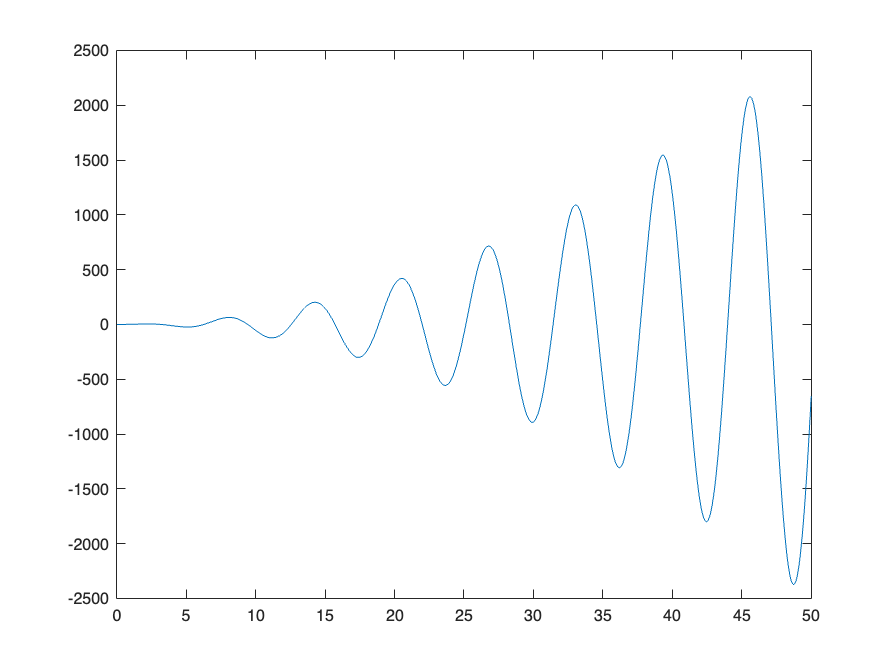

h = 0.01;
x = 0:h:50;
f = x.^2.*sin(x);
plot(x,f)

### 1.3 Array and Array (different but compatible size -- only know the basics )

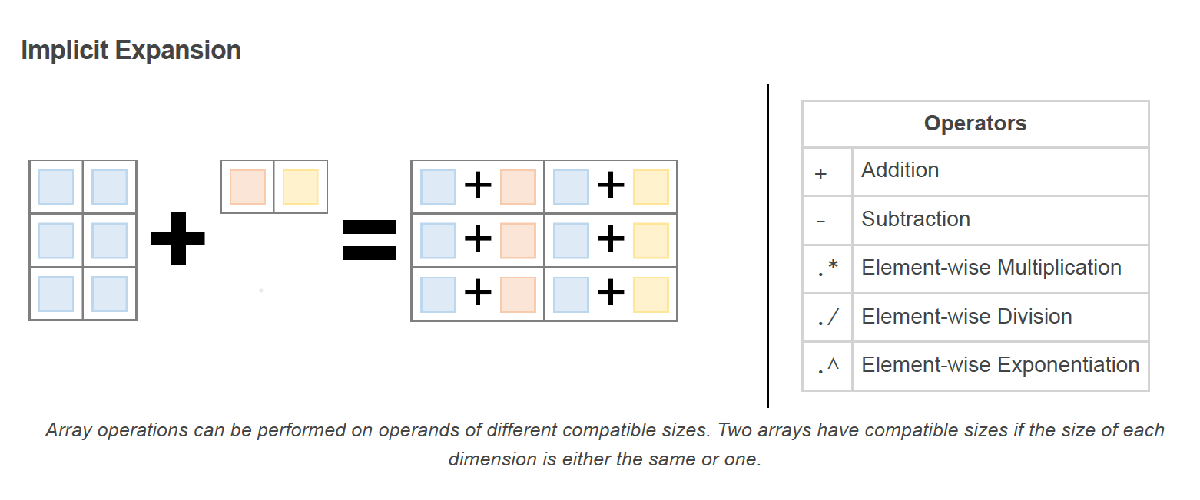

This feature has only been introduced in Matlab recently (after R2016b). The requirement is only about knowing that there exists such kind of issue and trying to avoid making mistakes.

v = [1 2 3];
w = v';
w+v

ans =      2     3     4
     3     4     5
     4     5     6


A = ones(3);
A.*w

ans =      1     1     1
     2     2     2
     3     3     3


A.*v

ans =      1     2     3
     1     2     3
     1     2     3


## 2. **Functions of Arrays**

### **2.1 Matlab Built-in Array Functions**

Many matlab built-in functions accept the input as the array, and output the element-wise value as another array --  convenient for usage.

v = -10:10;
exp(v)

ans = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0007    0.0020    0.0055    0.0148    0.0403    0.1097    0.2981    0.8103    2.2026


sin(v).*cos(v)

ans =    -0.4565    0.3755    0.1440   -0.4953    0.2683    0.2720   -0.4947    0.1397    0.3784   -0.4546         0    0.4546   -0.3784   -0.1397    0.4947   -0.2720   -0.2683    0.4953   -0.1440   -0.3755    0.4565


log(abs(v)) %natrual log with base e

ans =     2.3026    2.1972    2.0794    1.9459    1.7918    1.6094    1.3863    1.0986    0.6931         0      -Inf         0    0.6931    1.0986    1.3863    1.6094    1.7918    1.9459    2.0794    2.1972    2.3026


***Example 3: Plot Parametric Curves***

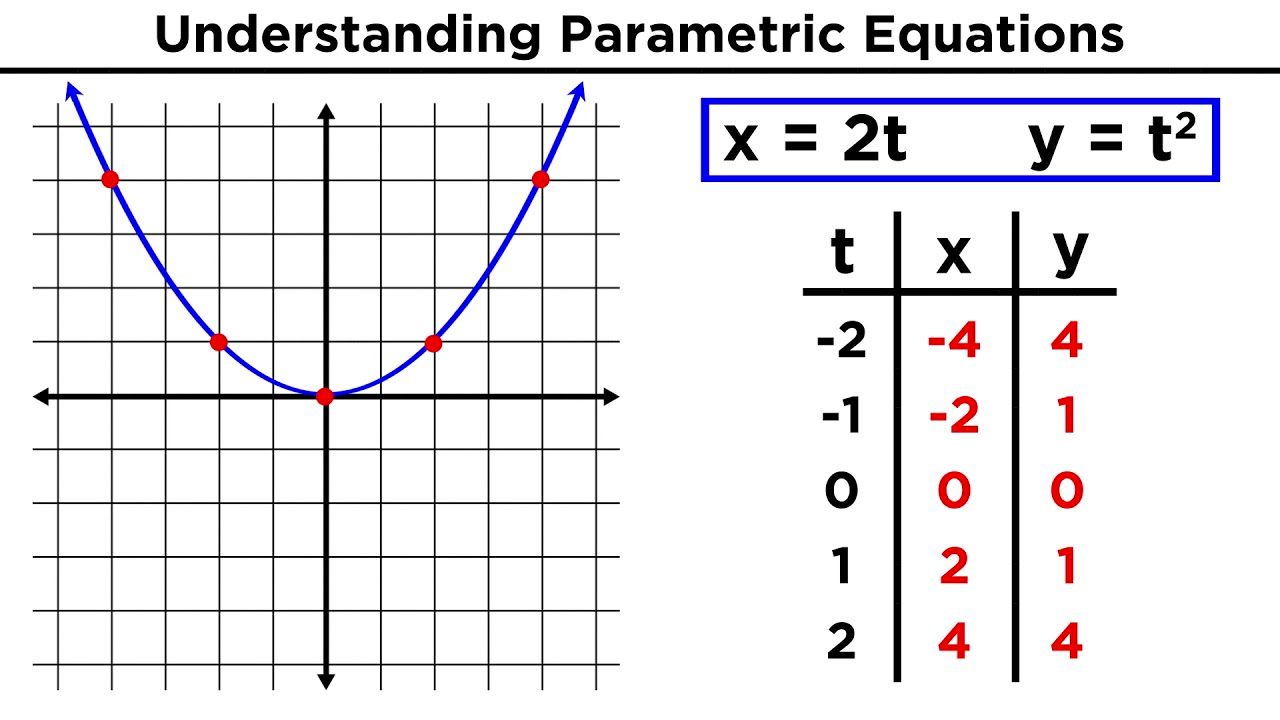

(the values of x and y are controlled by the parameter t)

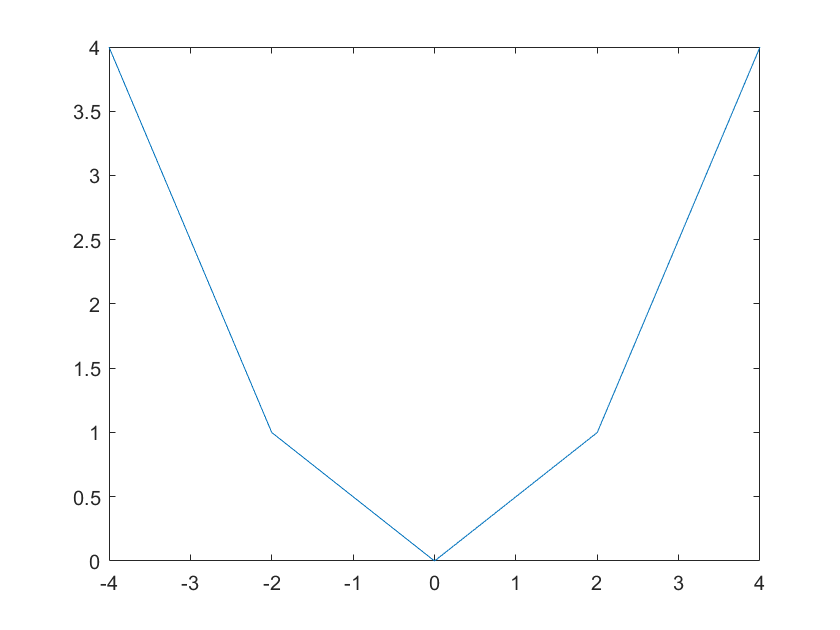

t = -2:1:2;
x = 2*t;
y = t.^2;
plot(x,y) % we only have 5 data points

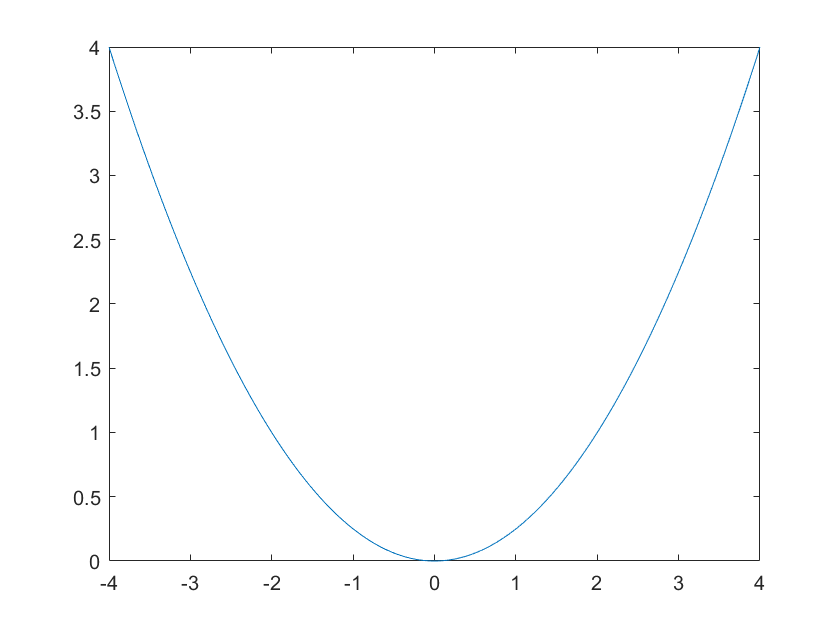

t2 = -2:1e-2:2;
x = 2*t2;
y = t2.^2;
plot(x,y)

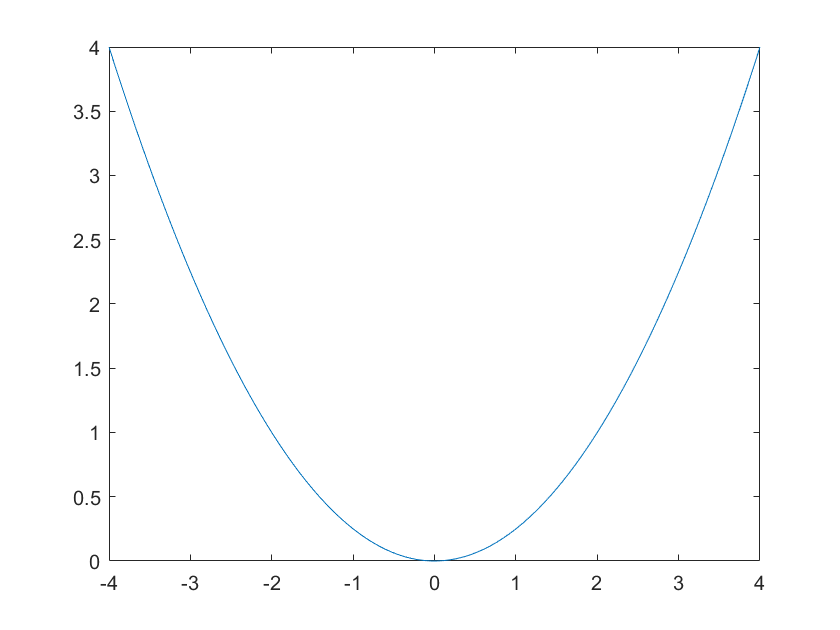

t3 = linspace(-2,2,100); % we can also use "linspace"
x = 2*t3;
y = t3.^2;
plot(x,y)

### ***In-class Exercise 3***

Plot the following Curve


$$\left\lbrace \begin{array}{ll}
x\left(t\right)=\left(2-2\sin \left(t\right)+\sin \left(t\right)\sqrt{\left|\cos \left(t\right)\right|}\right)\cos \left(t\right) & \\
y\left(t\right)=\left(2-2\sin \left(t\right)+\sin \left(t\right)\sqrt{\left|\cos \left(t\right)\right|}\right)\sin \left(t\right) & 
\end{array}\right.$$

$$0\le t\le 2\pi$$


**Hint:** [here](https://www.mathworks.com/help/matlab/matlab_prog/operator-precedence.html) is the systematic summarize of Matlab operator precedence. As a general rule:

operators in the same level are executed from left to right; the overall level is: ( )  **>**  ' and ^  **>**  unary sign +/-   **>**  * or /   **>**  + or - (binary)    **>**   colon :    **>** logical

### **2.2 **Statistical Functions of Arrays

These functions output a scalar if the input is one-dimensional array.

v = 1:10;
sum(v)
mean(v)
std(v)
var(v)

## 3. **Numerical Integral**

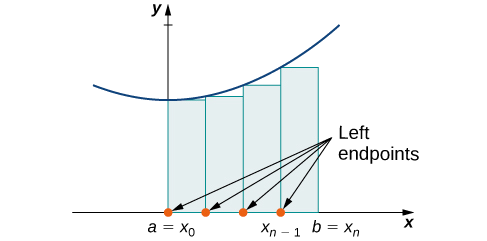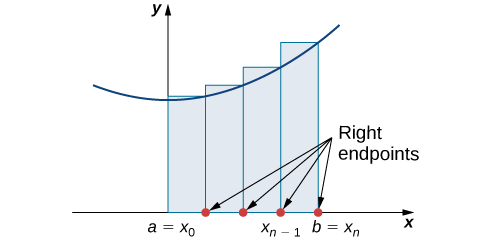

The straightforward way to approxiamte integral is to use **direct definition of Rieman sum** (or the geometrical meaning -- area under the curve). 

Suppose that we have the evenly-spaced partition of interval [a,b], and denote the points as $a=x_0 <x_1 <\ldotp \ldotp \ldotp <x_{n-1} <x_n =b$ and step size $h=\frac{b-a}{n}={x_i -x}_{i-1}$ . 

Thus, we have two formulas to approximate definite integral:

**left-end formula:** $h\sum_{i=1}^n f\left(x_{i-1} \right)=h\left(f\left(x_0 \right)+f\left(x_1 \right)+\ldotp \ldotp \ldotp +f\left(x_{n-1} \right)\right)\;\;\;$

**right-end formula: **$h\sum_{i=1}^n f\left(x_i \right)=h\left(f\left(x_1 \right)+f\left(x_2 \right)+\ldotp \ldotp \ldotp +f\left(x_n \right)\right)\;\;\;$

***Example 4: numerical integral of sin(x) from ****0**** to ***$2\pi$

n = 200; %number of intervals
a = 0;
b = 2*pi;
h = (b-a)/n; % step size
x = a:h:b % linspace(a,b,n+1)
f = sin(x);
int_left = h*sum(f(1:end-1))
int_right = h*sum(f(2:end))
int_left - int_right

x =          0    0.0314    0.0628    0.0942    0.1257    0.1571    0.1885    0.2199    0.2513    0.2827    0.3142    0.3456    0.3770    0.4084    0.4398    0.4712    0.5027    0.5341    0.5655    0.5969    0.6283    0.6597    0.6912    0.7226    0.7540    0.7854    0.8168    0.8482    0.8796    0.9111    0.9425    0.9739    1.0053    1.0367    1.0681    1.0996    1.1310    1.1624    1.1938    1.2252    1.2566    1.2881    1.3195    1.3509    1.3823    1.4137    1.4451    1.4765    1.5080    1.5394


int_left = -5.0574e-17

int_right = -5.8269e-17

ans = 7.6947e-18

### ***In-class Exercise 4***

Use both the **left-end formula **and** right-end formula** to calculate $\int_0^{\pi } \sin \left(x\right)\textrm{dx}$ with n = 100.

## 4. Other useful links

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h](https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h)

**Yasmeen Baki**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG](https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG) 